# MATLAB CODE - LABORATORIO 2

clear variables;

## **NB! Set the correct name of the com port you wish to use**

COMPORT_NAME = 'COM6';

## **Loading the color image file**

[file_load,path_load] = uigetfile('*.*');
if isequal(file_load,0)
   exit;
end



## **Loading the NIR image file**

% [file_load_nir,path_load_nir] = uigetfile('*.*');
% if isequal(file_load_nir,0)
%    exit;
% end

## Creating the byte vector to send

3-dimensional matrix of the color image

color_image_matrix = imread(fullfile(path_load,file_load));

% number of pixels in image width
image_x_pixel_count = size(color_image_matrix,1);
% number of pixels in height of the image
image_y_pixel_count = size(color_image_matrix,2);
% number of pixels in the image
image_pixel_count = image_x_pixel_count * image_y_pixel_count;

% numero di byte dell'immagine a colori
color_image_byte_count = image_pixel_count * 3;
% numero di byte dell'immagine in bianco nero
bw_image_byte_count = image_pixel_count;

% matrice a 3 dimensioni (una per colore) dell'immagine in bianco nero.
% tutte e tre le componenti verranno riempite con gli stessi dati
% elaborati dall'fpga
bw_image_matrix = zeros(image_x_pixel_count,image_y_pixel_count,3,'uint8');

% I build the vector of the bytes r-g-b-r-g-b .. that make up the color image
color_image_vector = zeros(1,color_image_byte_count,'uint8');
color_image_vector(1:3:color_image_byte_count) = color_image_matrix(:,:,1);
color_image_vector(2:3:color_image_byte_count) = color_image_matrix(:,:,2);
color_image_vector(3:3:color_image_byte_count) = color_image_matrix(:,:,3);


## Creating the byte vector to send NIR

3-dimensional matrix of the NIR image

% nir_image_matrix = imread(fullfile(path_load_nir,file_load_nir));
% 
% % number of pixels in image width
% nir_image_x_pixel_count = size(color_image_matrix,1);
% % number of pixels in height of the image
% nir_image_y_pixel_count = size(color_image_matrix,2);
% % number of pixels in the image
% nir_image_pixel_count = nir_image_x_pixel_count * nir_image_y_pixel_count;
% 
% % numero di byte dell'immagine a colori
% nir_image_byte_count = nir_image_pixel_count * 3;
% % numero di byte dell'immagine in bianco nero
% nir_bw_image_byte_count = nir_image_pixel_count;
% 
% % matrice a 3 dimensioni (una per colore) dell'immagine in bianco nero.
% % tutte e tre le componenti verranno riempite con gli stessi dati
% % elaborati dall'fpga
% nir_bw_image_matrix = zeros(nir_image_x_pixel_count,nir_image_y_pixel_count,3,'uint8');
% 
% % I build the vector of the bytes r-g-b-r-g-b .. that make up the color image
% nir_image_vector = zeros(1,nir_image_byte_count,'uint8');
% nir_image_vector(1:3:nir_image_byte_count) = nir_image_matrix(:,:,1);
% nir_image_vector(2:3:nir_image_byte_count) = nir_image_matrix(:,:,2);
% nir_image_vector(3:3:nir_image_byte_count) = nir_image_matrix(:,:,3);

## Sending and receiving data

Instantiate the serial port and configure the parameters

serial_com = serial(COMPORT_NAME);
serial_com.BaudRate = 115200;
serial_com.InputBufferSize = bw_image_byte_count;
serial_com.OutputBufferSize = color_image_byte_count;
serial_com.Timeout = 200;

% apro il canale di comunicazione
fopen(serial_com);
% invio i dati dell'immagine a colori
fwrite(serial_com,color_image_vector);
% recupero i  dati dell'immagine in bianco nero
bw_image_vector = fread(serial_com);
% chiudo il canale di comunicazione ed elimono l'istanza della porta
fclose(serial_com);

% % apro il canale di comunicazione
% fopen(serial_com);
% % invio i dati dell'immagine a colori
% fwrite(serial_com,nir_image_vector);
% % recupero i  dati dell'immagine in bianco nero
% nir_bw_image_vector = fread(serial_com);
% % chiudo il canale di comunicazione ed elimono l'istanza della porta
% fclose(serial_com);
% delete(serial_com);

## Saving the resulting black-and-white image file

except the data received in the matrix created previously

bw_image_matrix(:,:,1)=reshape(bw_image_vector,[image_x_pixel_count,image_y_pixel_count]);
bw_image_matrix(:,:,2)=bw_image_matrix(:,:,1);
bw_image_matrix(:,:,3)=bw_image_matrix(:,:,1);

[file_save,path_save] = uiputfile('*.png');
if isequal(file_save,0)
   exit;
end
imwrite(bw_image_matrix, fullfile(path_save,file_save));

% nir_bw_image_matrix(:,:,1)=reshape(nir_bw_image_vector,[nir_image_x_pixel_count,nir_image_y_pixel_count]);
% nir_bw_image_matrix(:,:,2)=nir_bw_image_matrix(:,:,1);
% nir_bw_image_matrix(:,:,3)=nir_bw_image_matrix(:,:,1);
% 
% [file_save,path_save] = uiputfile('*.png');
% if isequal(file_save,0)
%    exit;
% end
% imwrite(nir_bw_image_matrix, fullfile(path_save,file_save));

## Display of the final result

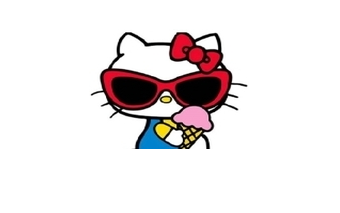

figure, imshow(color_image_matrix);

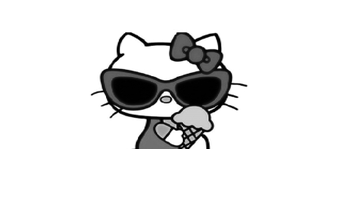

figure, imshow(bw_image_matrix);


% figure, imshow(nir_image_matrix);
% figure, imshow(nir_bw_image_matrix);